Compare runtimes for problems which were solved in general robotics toolbox (grt)

runtimes_sp1 = run_timing_test(@sp1_setup, {@sp1_linear_timing_run, @sp1_grt_timing_run}, 100, 10)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp1 = 1.0e-05 *

    0.2910    0.5280
    0.2310    0.4140
    0.2280    0.5560
    0.2280    0.3810
    0.2290    0.3650
    0.2300    0.4930
    0.2260    0.3610
    0.2270    0.3550
    0.2280    0.3440
    0.2270    0.3510


ans = 2.2667e-06

ans = 3.5275e-06

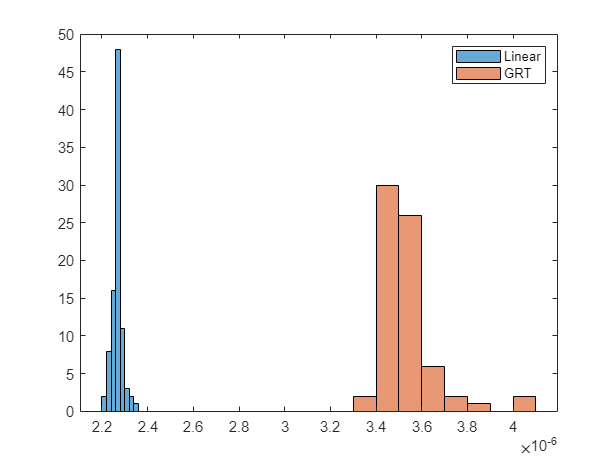

[rt_filt_sp1_linear, rt_filt_sp1_grt] = compare_runs(runtimes_sp1);

runtimes_sp2 = run_timing_test(@sp2_setup, {@sp2_linear_timing_run, @sp2_grt_timing_run}, 100, 10)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp2 = 1.0e-04 *

    0.2404    0.3290
    0.2180    0.2610
    0.2178    0.2576
    0.2348    0.2999
    0.2233    0.2683
    0.2178    0.2659
    0.2171    0.2668
    0.2339    0.2727
    0.2412    0.2660
    0.2183    0.2651


ans = 2.2941e-05

ans = 2.6718e-05

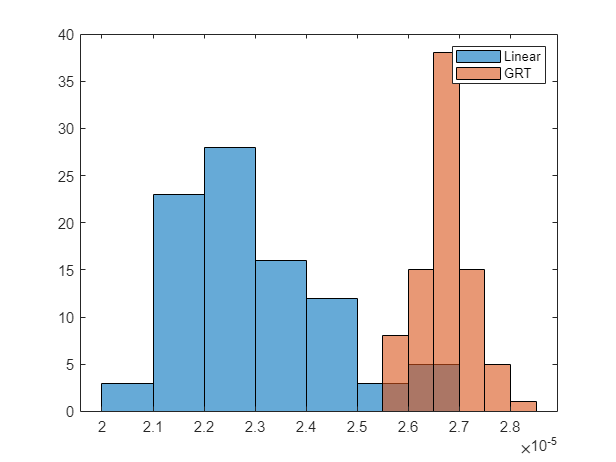

[rt_filt_sp2_linear, rt_filt_sp2_grt] = compare_runs(runtimes_sp2);

runtimes_sp3 = run_timing_test(@sp3_setup, {@sp3_linear_timing_run, @sp3_grt_timing_run}, 100, 10)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp3 = 1.0e-04 *

    0.0672    0.0585
    0.0527    0.0534
    0.0522    0.0522
    0.0522    0.0515
    0.0511    0.0519
    0.0511    0.0537
    0.0511    0.0529
    0.0513    0.0530
    0.0526    0.0536
    0.0518    0.0524


ans = 4.9361e-06

ans = 5.3485e-06

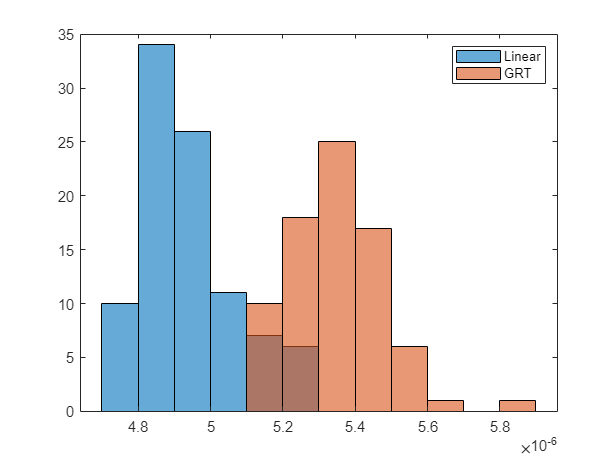

[rt_filt_sp3_linear, rt_filt_sp3_grt] = compare_runs(runtimes_sp3);

runtimes_sp4 = run_timing_test(@sp4_setup, {@sp4_linear_timing_run, @sp4_grt_timing_run}, 100, 10)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp4 = 1.0e-04 *

    0.0702    0.0738
    0.0570    0.0619
    0.0555    0.0613
    0.0558    0.0604
    0.0554    0.0603
    0.0564    0.0604
    0.1398    0.0602
    0.0913    0.0664
    0.0577    0.0621
    0.0576    0.0616


ans = 5.6128e-06

ans = 6.0973e-06

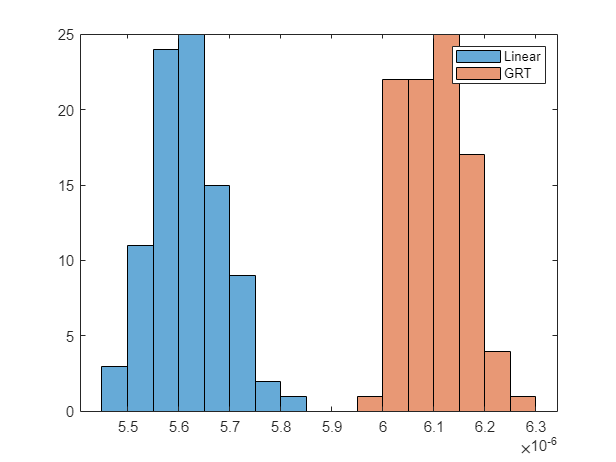

[rt_filt_sp4_linear, rt_filt_sp4_grt] = compare_runs(runtimes_sp4);

Runtimes for problems unique to this repo

runtimes_sp2_extended = run_timing_test(@sp2_ext_setup, {@sp2_ext_timing_run}, 100, 10);

    0.2000

    0.4000

    0.6000

    0.8000



ans = 2.5973e-05

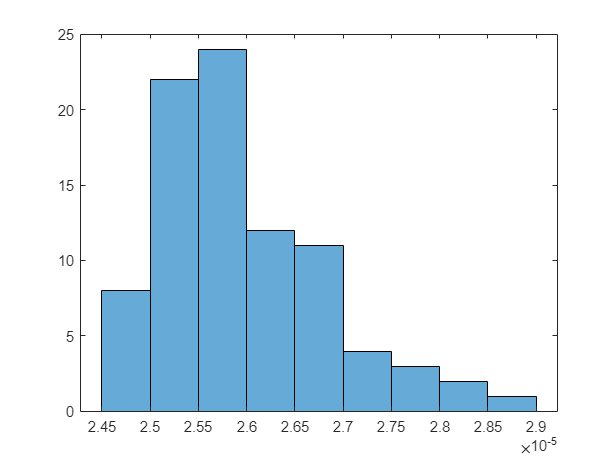

rt_filt_sp2_ext = plot_single_run(runtimes_sp2_extended);

runtimes_sp5 = run_timing_test(@sp5_setup, {@sp5_timing_run}, 100, 10);

    0.2000

    0.4000

    0.6000

    0.8000



ans = 8.7806e-05

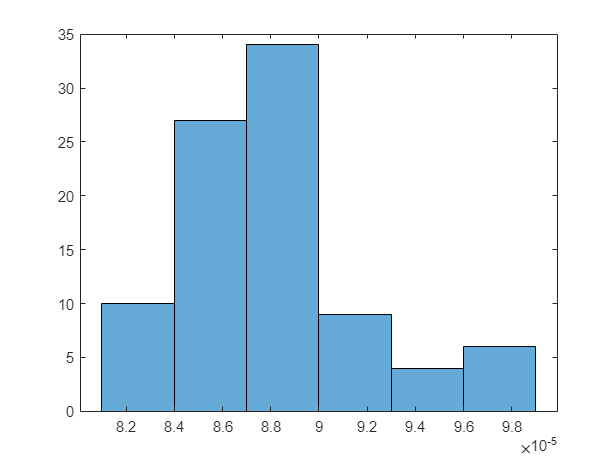

rt_filt_sp5 = plot_single_run(runtimes_sp5);

runtimes_sp5 = run_timing_test(@sp5_setup, {@sp5_timing_run, @sp5_mex_timing_run}, 100, 10);

    0.2000

    0.4000

    0.6000

    0.8000



[rt_filt_sp5, rt_filt_sp5_mex] = compare_runs(runtimes_sp5);

ans = 9.0722e-05

ans = 3.9748e-05

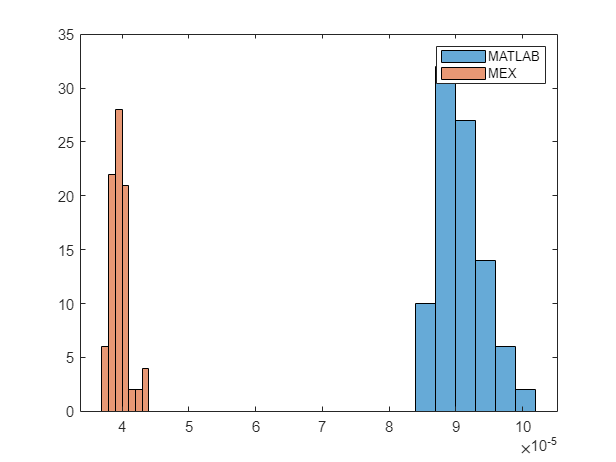

legend("MATLAB", "MEX")

%mean(rt_filt_sp5)

runtimes_sp6 = run_timing_test(@sp6_setup, {@sp6_timing_run}, 100, 10);

    0.2000

    0.4000

    0.6000

    0.8000



ans = 1.3249e-04

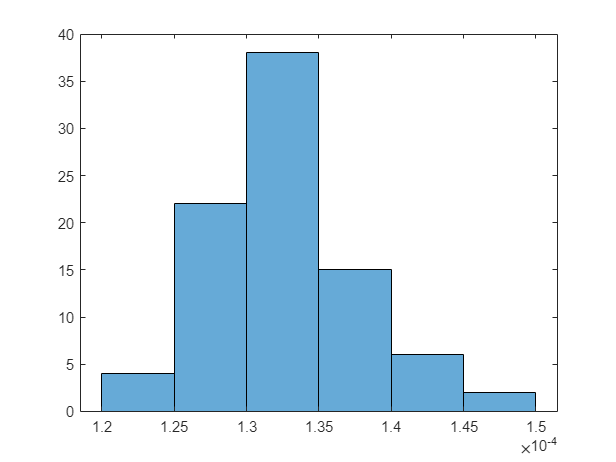

rt_filt_sp6 = plot_single_run(runtimes_sp6);

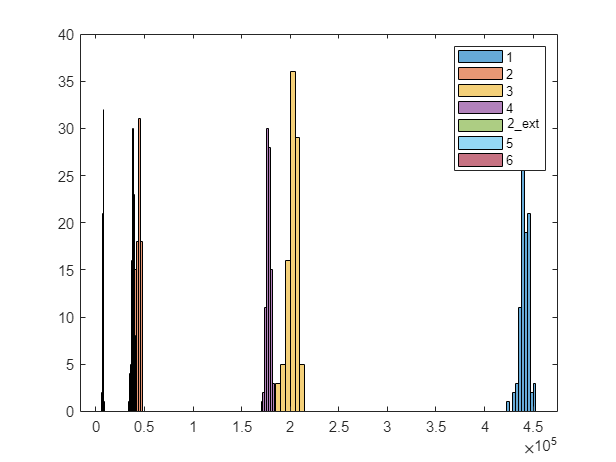

histogram(1./rt_filt_sp1_linear); hold on
histogram(1./rt_filt_sp2_linear);
histogram(1./rt_filt_sp3_linear);
histogram(1./rt_filt_sp4_linear);
histogram(1./rt_filt_sp2_ext);
histogram(1./rt_filt_sp5);
histogram(1./rt_filt_sp6); hold off
legend(["1", "2","3","4","2\_ext","5","6"])

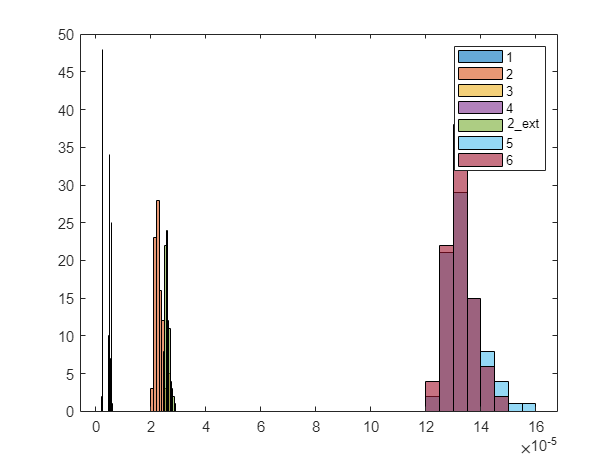


histogram(rt_filt_sp1_linear); hold on
histogram(rt_filt_sp2_linear);
histogram(rt_filt_sp3_linear);
histogram(rt_filt_sp4_linear);
histogram(rt_filt_sp2_ext);
histogram(rt_filt_sp5);
histogram(rt_filt_sp6); hold off
legend(["1", "2","3","4","2\_ext","5","6"])

function [runtimes_linear, runtimes_grt] = compare_runs(runtimes)
    runtimes_linear = rmoutliers(runtimes(:,1));
    runtimes_grt = rmoutliers(runtimes(:,2));
    
    mean(runtimes_linear)
    mean(runtimes_grt)
    
    histogram(runtimes_linear); hold on
    histogram(runtimes_grt); hold off
    legend("Linear", "GRT")
end

function  runtimes= plot_single_run(runtimes)
    runtimes = rmoutliers(runtimes(:,1));
    mean(runtimes)
    histogram(runtimes);
end


function S = sp1_linear_timing_run(P)
    S = subproblem1_linear(P.p1,P.p2,P.k);
end

function S = sp1_grt_timing_run(P)
    S = subproblem1(P.p1,P.p2,P.k);
end

function P = sp1_setup()
P.p1 = rand([3 1])*10;
P.k = rand([3 1]);
P.k = P.k/norm(P.k);
P.theta = rand*2*pi-pi;

P.p2 = rot(P.k,P.theta)*P.p1;
end

function S = sp2_linear_timing_run(P)
    [S.t1,S.t2] = subproblem2_linear(P.p1,P.p2,P.k1,P.k2);
end

function S = sp2_grt_timing_run(P)
    [S.t1,S.t2] = subproblem2(P.p2,P.p1,P.k1,P.k2); % Flipped p1, p2
end

function P = sp2_setup()
    P.p1 = rand([3 1])*10;

    P.k1 = rand([3 1]);
    P.k1 = P.k1/norm(P.k1);
    
    P.k2 = rand([3 1]);
    P.k2 = P.k2/norm(P.k2);
    
    P.theta1 = rand()*2*pi-pi;
    P.theta2 = rand()*2*pi-pi;
    
    P.p2 = rot(P.k2, -P.theta2)*rot(P.k1,P.theta1)*P.p1;
end

function S = sp3_linear_timing_run(P)
    S = subproblem3_linear(P.p1,P.p2,P.k,P.d);
end

function S = sp3_grt_timing_run(P)
    S = fixed_subproblem3(P.p1,P.p2,P.k,P.d);
end

function P = sp3_setup()
    P.p1 = rand([3 1])*10;
    P.p2 = rand([3 1])*10;
    P.k = rand([3 1]);
    P.k = P.k/norm(P.k);
    P.theta = rand*2*pi-pi;
    
    P.d = norm(P.p2-rot(P.k,P.theta)*P.p1);
end

function S = sp4_linear_timing_run(P)
    S = subproblem4_linear(P.h,P.p,P.k,P.d);
end

function S = sp4_grt_timing_run(P)
    S = subproblem4(P.h,P.p,P.k,P.d);
end

function P = sp4_setup()
    P.p = rand([3 1])*10;
    P.k = rand([3 1]);
    P.k = P.k/norm(P.k);
    P.h = rand([3 1]);
    P.h = P.h/norm(P.h);
    P.theta = rand*2*pi-pi;
    
    P.d = P.h'*rot(P.k,P.theta)*P.p;
end

function P=sp2_ext_setup()
    P.p0 = rand_vec;
    P.p1 = rand_vec;
    
    P.k1 = rand_normal_vec;
    P.k2 = rand_normal_vec;
    
    P.theta1 = rand_angle;
    P.theta2 = rand_angle;
    
    P.p2 = rot(P.k2, -P.theta2)*(P.p0 + rot(P.k1,P.theta1)*P.p1);
end

function S = sp2_ext_timing_run(P)
    [S.t1,S.t2] = subproblem2_linear_extended(P.p0,P.p1,P.p2,P.k1,P.k2);
end


function P = sp5_setup()
    P.p1 = rand_vec;
    P.p2 = rand_vec;
    P.p3 = rand_vec;
    
    P.k1 = rand_normal_vec;
    P.k2 = rand_normal_vec;
    P.k3 = rand_normal_vec;
    
    P.theta1 = rand_angle;
    P.theta2 = rand_angle;
    P.theta3 = rand_angle;
    
    P.p0 = -(rot(P.k1,P.theta1)*P.p1 -rot(P.k2,P.theta2)*(P.p2+rot(P.k3,P.theta3)*P.p3));
end

function S= sp5_timing_run(P)
    [S.t1, S.t2, S.t3] = subproblem5_linear(P.p0,P.p1,P.p2,P.p3,P.k1,P.k2,P.k3);
end

function S= sp5_mex_timing_run(P)
    [S.t1, S.t2, S.t3] = subproblem5_linear_mex(P.p0,P.p1,P.p2,P.p3,P.k1,P.k2,P.k3);
end


function P = sp6_setup()
    P.p1 = rand_vec;
    P.p2 = rand_vec;
    P.p3 = rand_vec;
    P.p4 = rand_vec;
    P.k1 = rand_normal_vec;
    P.k2 = rand_normal_vec;
    P.h = rand_normal_vec;
    
    P.theta1 = rand_angle;
    P.theta2 = rand_angle;
    
    P.d1 =  P.h'* rot(P.k1, P.theta1) * P.p1 + P.h'* rot(P.k2, P.theta2) * P.p2;
    P.d2 =  P.h'* rot(P.k1, P.theta1) * P.p3 + P.h'* rot(P.k2, P.theta2) * P.p4;
end

function S = sp6_timing_run(P)
    [S.t1, S.t2] = subproblem6_linear( ...
    P.h, P.k1, P.k2, P.p1, P.p2, P.p3, P.p4, P.d1, P.d2);
end

function v = rand_normal_vec()
    v = rand([3 1]);
    v = v/norm(v);
end

function v = rand_vec()
    v = rand([3 1]);
end

function theta = rand_angle()
    theta = rand*2*pi-pi;
end